MBON_responseA=zeros(100,100);
MBON_responseB=zeros(100,100);
KC_responseA=zeros(2000,100,100);
KC_responseB=zeros(2000,100,100);
PN_responseA=zeros(50,100,100);
PN_responseB=zeros(50,100,100);

for seed=1:100
PN_KC_matrixA=pn_kc_matrix(50,2000,seed);
PN_KC_matrixB=pn_kc_matrix(50,2000,2*seed);

KC_MBON_matrixA=kc_mbon_matrix(2000);
KC_MBON_matrixB = KC_MBON_matrixA;

for odor =1:100
    PN_spikesA=pn_spikes(50,odor);
    PN_spikesB=PN_spikesA;
    PN_responseA(:,odor,seed)=PN_spikesA;
    PN_responseB(:,odor,seed)=PN_spikesB;

    KC_spikesA=kc_spikes(PN_KC_matrixA,PN_spikesA);
    KC_spikesB=kc_spikes(PN_KC_matrixB,PN_spikesB);
    KC_responseA(:,odor,seed)=KC_spikesA;
    KC_responseB(:,odor,seed)=KC_spikesB;
    MBON_responseA(odor,seed)=mbon_spikes(KC_MBON_matrixA,KC_spikesA);
    MBON_responseB(odor,seed)=mbon_spikes(KC_MBON_matrixB,KC_spikesB);
end

end

%to check the MBON responses are well correlated.
corr(MBON_responseA,MBON_responseB) 

ans =     0.9892    0.9821    0.9857    0.9830    0.9912    0.9836    0.9815    0.9810    0.9811    0.9852    0.9810    0.9854    0.9839    0.9887    0.9821    0.9830    0.9835    0.9815    0.9862    0.9885    0.9848    0.9817    0.9823    0.9819    0.9758    0.9800    0.9835    0.9888    0.9850    0.9820    0.9861    0.9835    0.9872    0.9836    0.9818    0.9850    0.9862    0.9836    0.9785    0.9888    0.9853    0.9851    0.9862    0.9821    0.9829    0.9840    0.9891    0.9856    0.9819    0.9832
    1.0000    0.9832    0.9849    0.9860    0.9884    0.9884    0.9851    0.9812    0.9835    0.9853    0.9873    0.9853    0.9854    0.9859    0.9825    0.9832    0.9837    0.9861    0.9875    0.9863    0.9852    0.9802    0.9857    0.9809    0.9771    0.9792    0.9859    0.9912    0.9841    0.9877    0.9882    0.9862    0.9887    0.9877    0.9854    0.9833    0.9875    0.9830    0.9722    0.9902    0.9867    0.9893    0.9867    0.9845    0.9865    0.9843    0.9866    0.9870    0.9841   

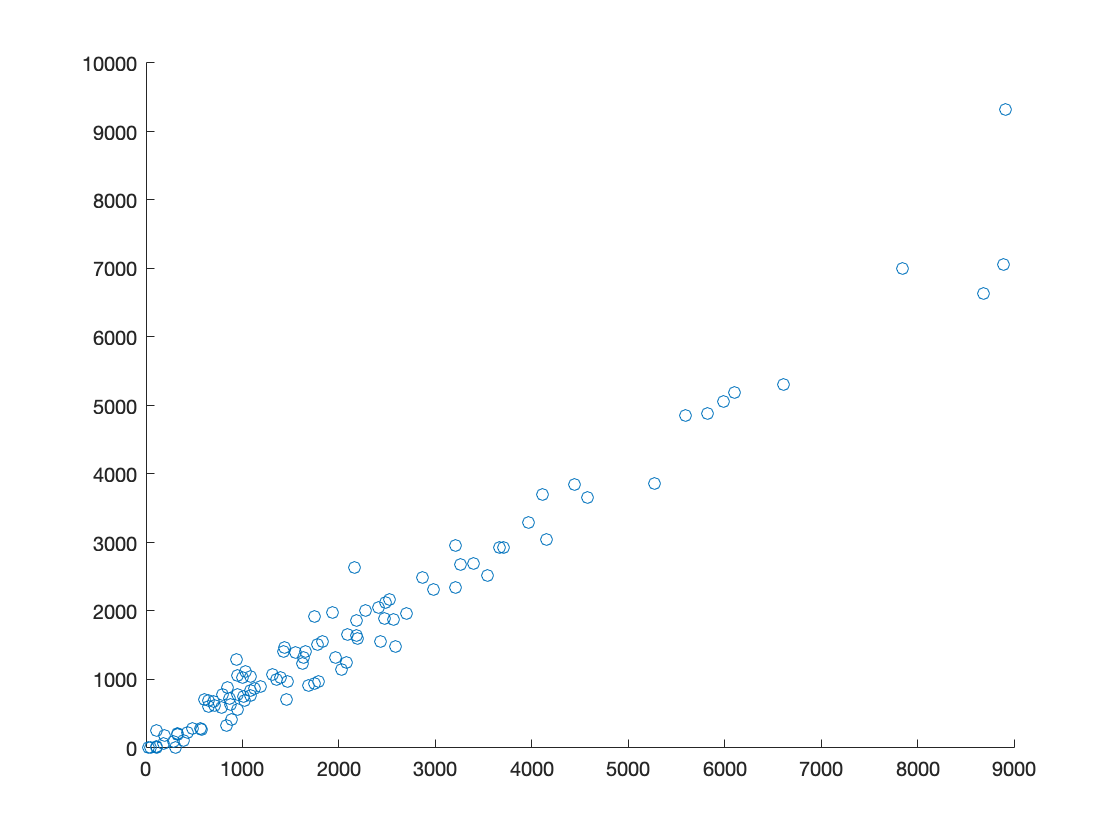

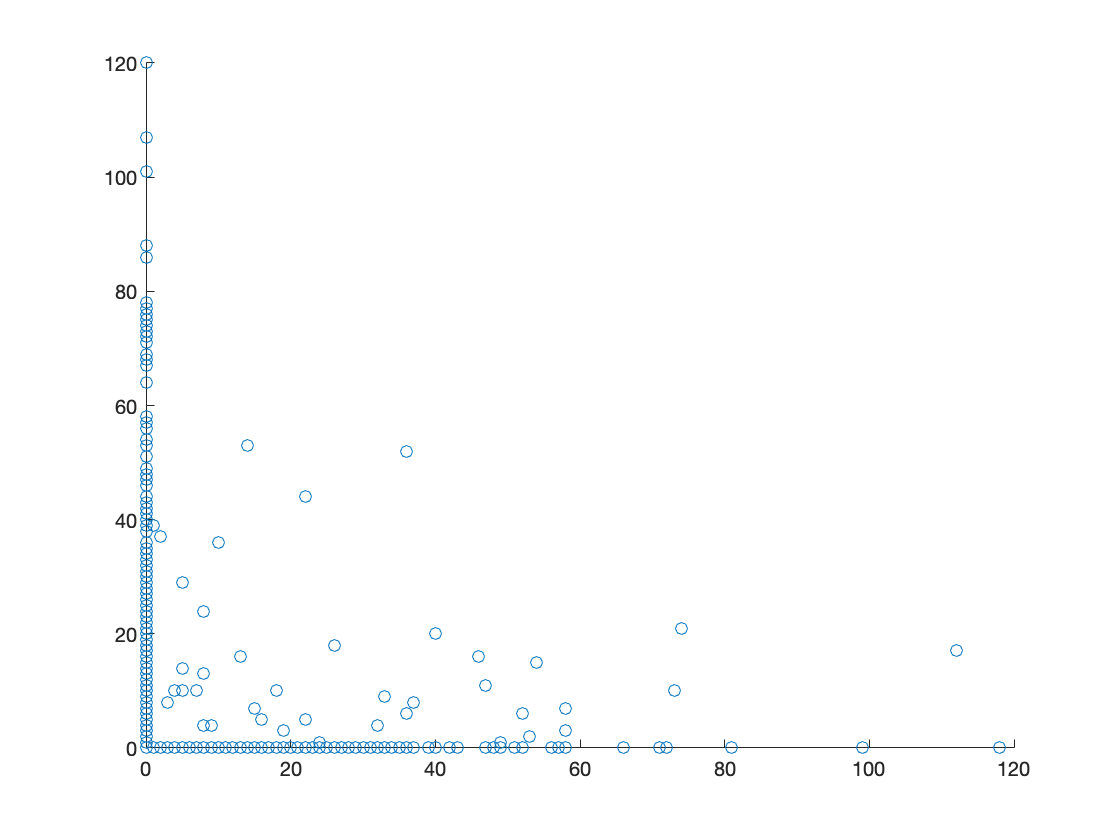

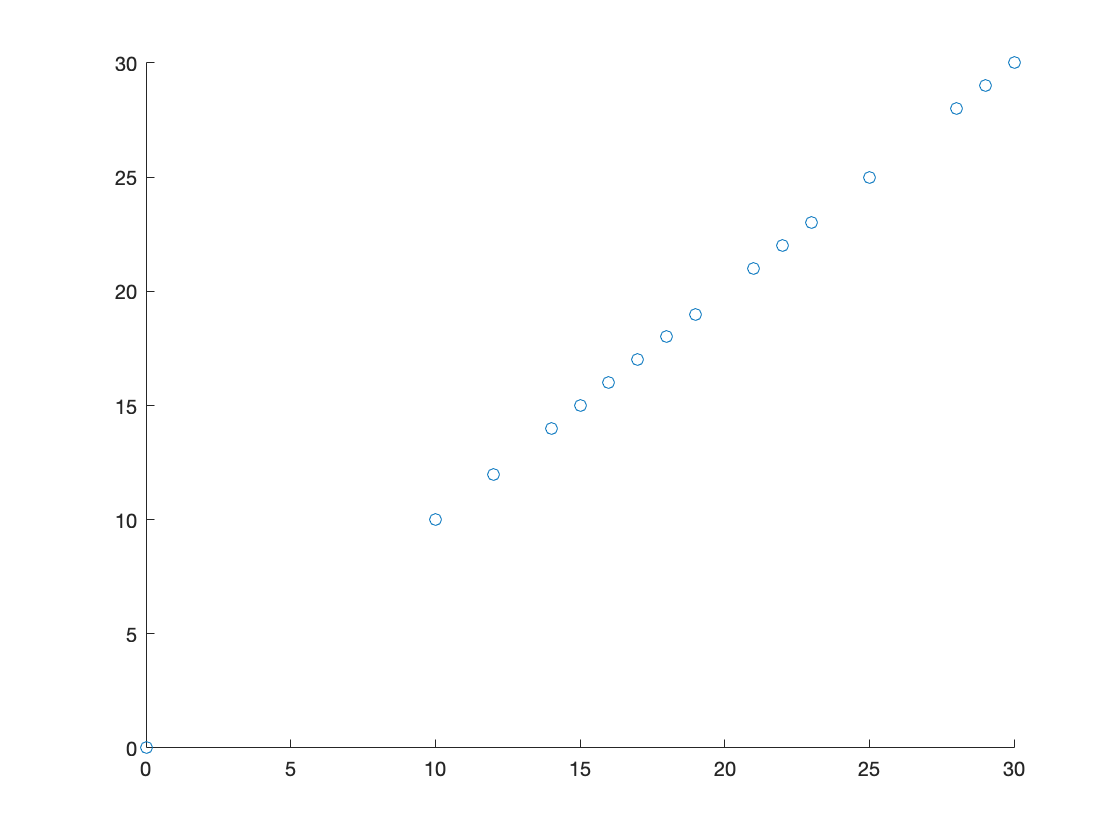

scatter(MBON_spikesA,MBON_spikesB) 

%PRED stereotypy for MBON responses
PREDstereotypy=zeros(4950,100);
for seed=1:100
PREDstereotypy(:,seed)=stereotypy(MBON_responseA(:,seed),MBON_responseB(:,seed));
end

%Taking mean across the 4950 odor pairs.
pred=mean(PREDstereotypy,1)'

pred =     0.7523
    0.7948
    0.7974
    0.7926
    0.7600
    0.7752
    0.7826
    0.7421
    0.7819
    0.7852


%Correlation between the MBON responses in the individuals.
cor=zeros(100,1);
for seed=1:100
    cor(seed,:)=correlation(MBON_responseA(:,seed),MBON_responseB(:,seed));
end

%Individual KC correlation 
KC_cor=zeros(2000,100);
for seed=1:100
    KC_cor(:,seed)= kc_correlation(KC_responseA(:,:,seed),KC_responseB(:,:,seed));
end
KC_cor(isnan(KC_cor))=[];

%PRED stereotypy of individual KCs
KC_indPREDstereotypy=zeros(2000,100);
for seed=1:100
    kcpred=kc_indpred(KC_responseA(:,:,seed),KC_responseB(:,:,seed));
    KC_indPREDstereotypy(:,seed)= kcpred;
    disp(seed);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100



%Correlation for the total KC response (all 2000 of them) between the two
%individuals
KC_totcor=zeros(100,1);
for seed=1:100
    KC_totcor(seed,:)= kc_totcor(KC_responseA(:,:,seed),KC_responseB(:,:,seed));
end
KC_totcor(isnan(KC_cor))=[];

%PRED stereotypy for the total KC responses of the two individuals.
KC_totPREDstereotypy=zeros(4950,100);
for seed=1:100
KC_totPREDstereotypy(:,seed)=kc_totpred(KC_responseA(:,:,seed),KC_responseB(:,:,seed));
disp(seed);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100



ans = 40

pred =     0.7523
    0.7948
    0.7974
    0.7926
    0.7600
    0.7752
    0.7826
    0.7421
    0.7819
    0.7852


%To use the gramm plotting package
addpath('/Users/raghaabhinaya/Desktop/gramm-master');
savepath /Users/raghaabhinaya/Desktop/gramm-master/pathdef.m

%Plot of Correlation vs PRED stereotypy of MBON responses
g=gramm('x',pred,'y',cor);
g.geom_point();
g.axe_property('YLim', [0.95 1], 'YGrid', 'on', 'YTick', 0.95:0.01:1, 'GridLineStyle', '--', 'TickDir', 'out');
g.axe_property('XLim', [0.5 0.9], 'XGrid', 'on', 'XTick', 0.5:0.1:0.9, 'GridLineStyle', '--', 'TickDir', 'out');
g.set_point_options("markers","o","base_size",15);
g.set_names('x','PRED stereotypy','y','Correlation stereotypy')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


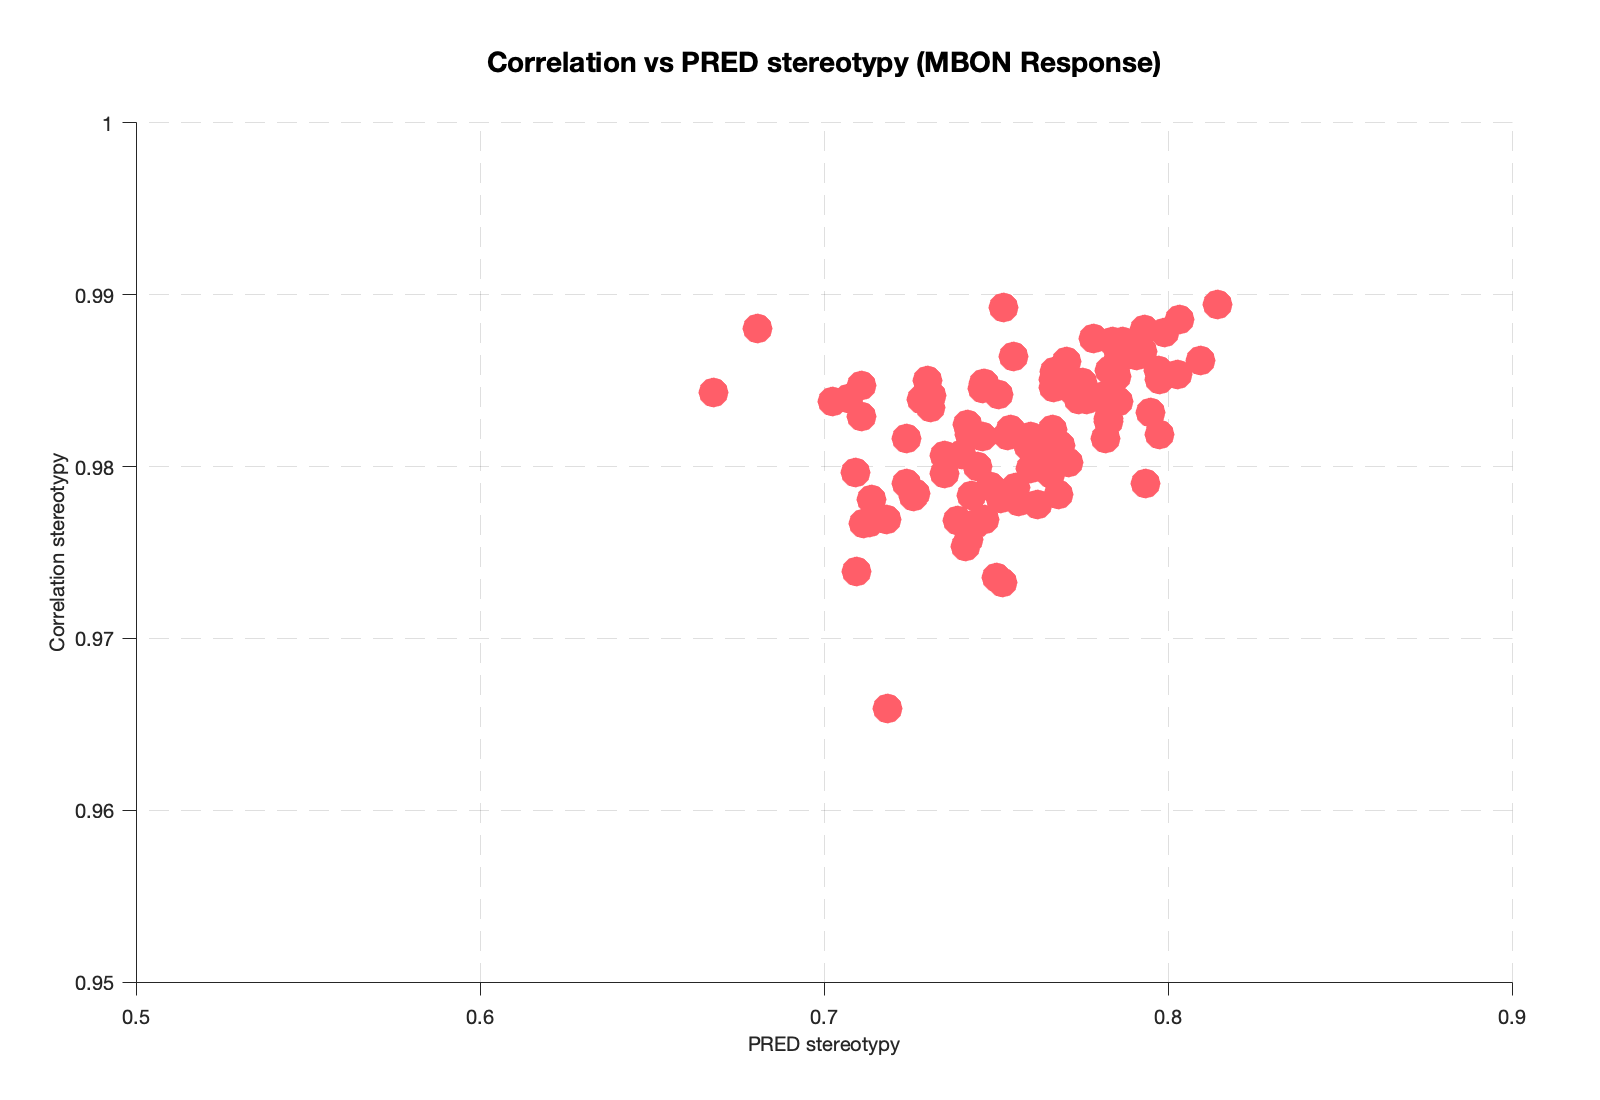

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


g.set_title("Correlation vs PRED stereotypy (MBON Response)");
figure('Position',[100 100 800 550]);
g.draw();

%Defining the cells to act as x values when plotting PRED and correlation
%values.

corrcell=cell(100,1);
for it=1:100
    corrcell(it,1)={'Correlation'};
end

predcell=cell(495000,1);
for it=1:495000
    predcell(it,1)={'PRED'};
end

no=size(KC_cor,2);
kc_corrcell=cell(no,1);
for it=1:no
    kc_corrcell(it,1)={'KC Correlation'};
end

kc_predcell=cell(nu,1);
for it=1:200000
    kc_predcell(it,1)={'KC PRED'};
end

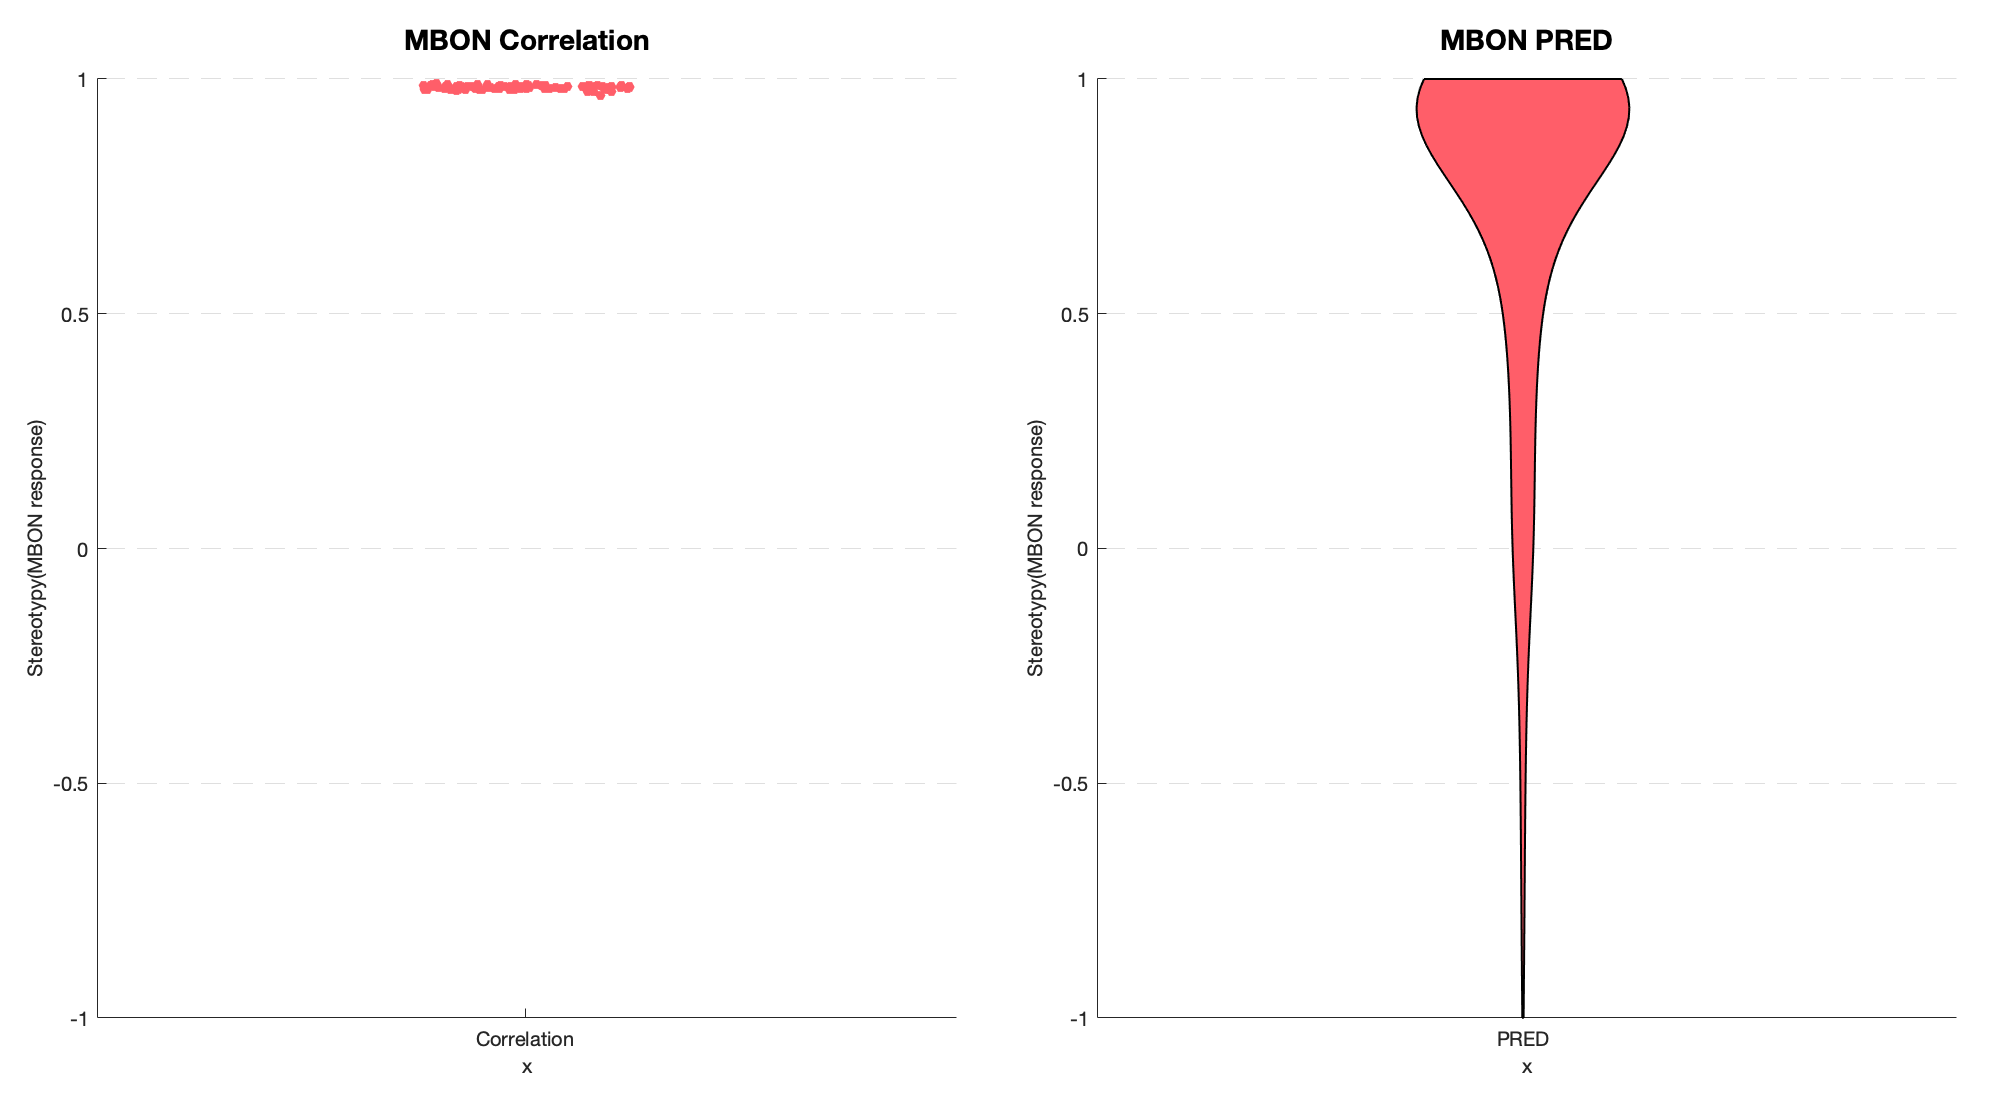


%Jittered scatter plot of MBON correlation
g(1,1)=gramm('x',corrcell(:,1),'y',cor);
g(1,1).geom_jitter('width',0.4,'height',0);
g(1,1).set_title('MBON Correlation');
g(1,1).set_names('y','Stereotypy(MBON response)');
g(1, 1).axe_property('YLim', [-1 1], 'YGrid', 'on', 'YTick', -1:0.5:1, 'GridLineStyle', '--');

%Violin plot of MBON PRED
g(1,2)=gramm('x',predcell(:,1),'y',PREDstereotypy(:));
g(1,2).set_title('MBON PRED');
g(1,2).set_names('y','Stereotypy(MBON response)');
g(1, 2).axe_property('YLim', [-1 1], 'YGrid', 'on', 'YTick', -1:0.5:1, 'GridLineStyle', '--');
g(1, 2).stat_violin('normalization', "width", 'fill', "face", 'width', 0.3, 'bandwidth', 0.15);

figure('Position',[100 100 1000 550]);

g.draw();

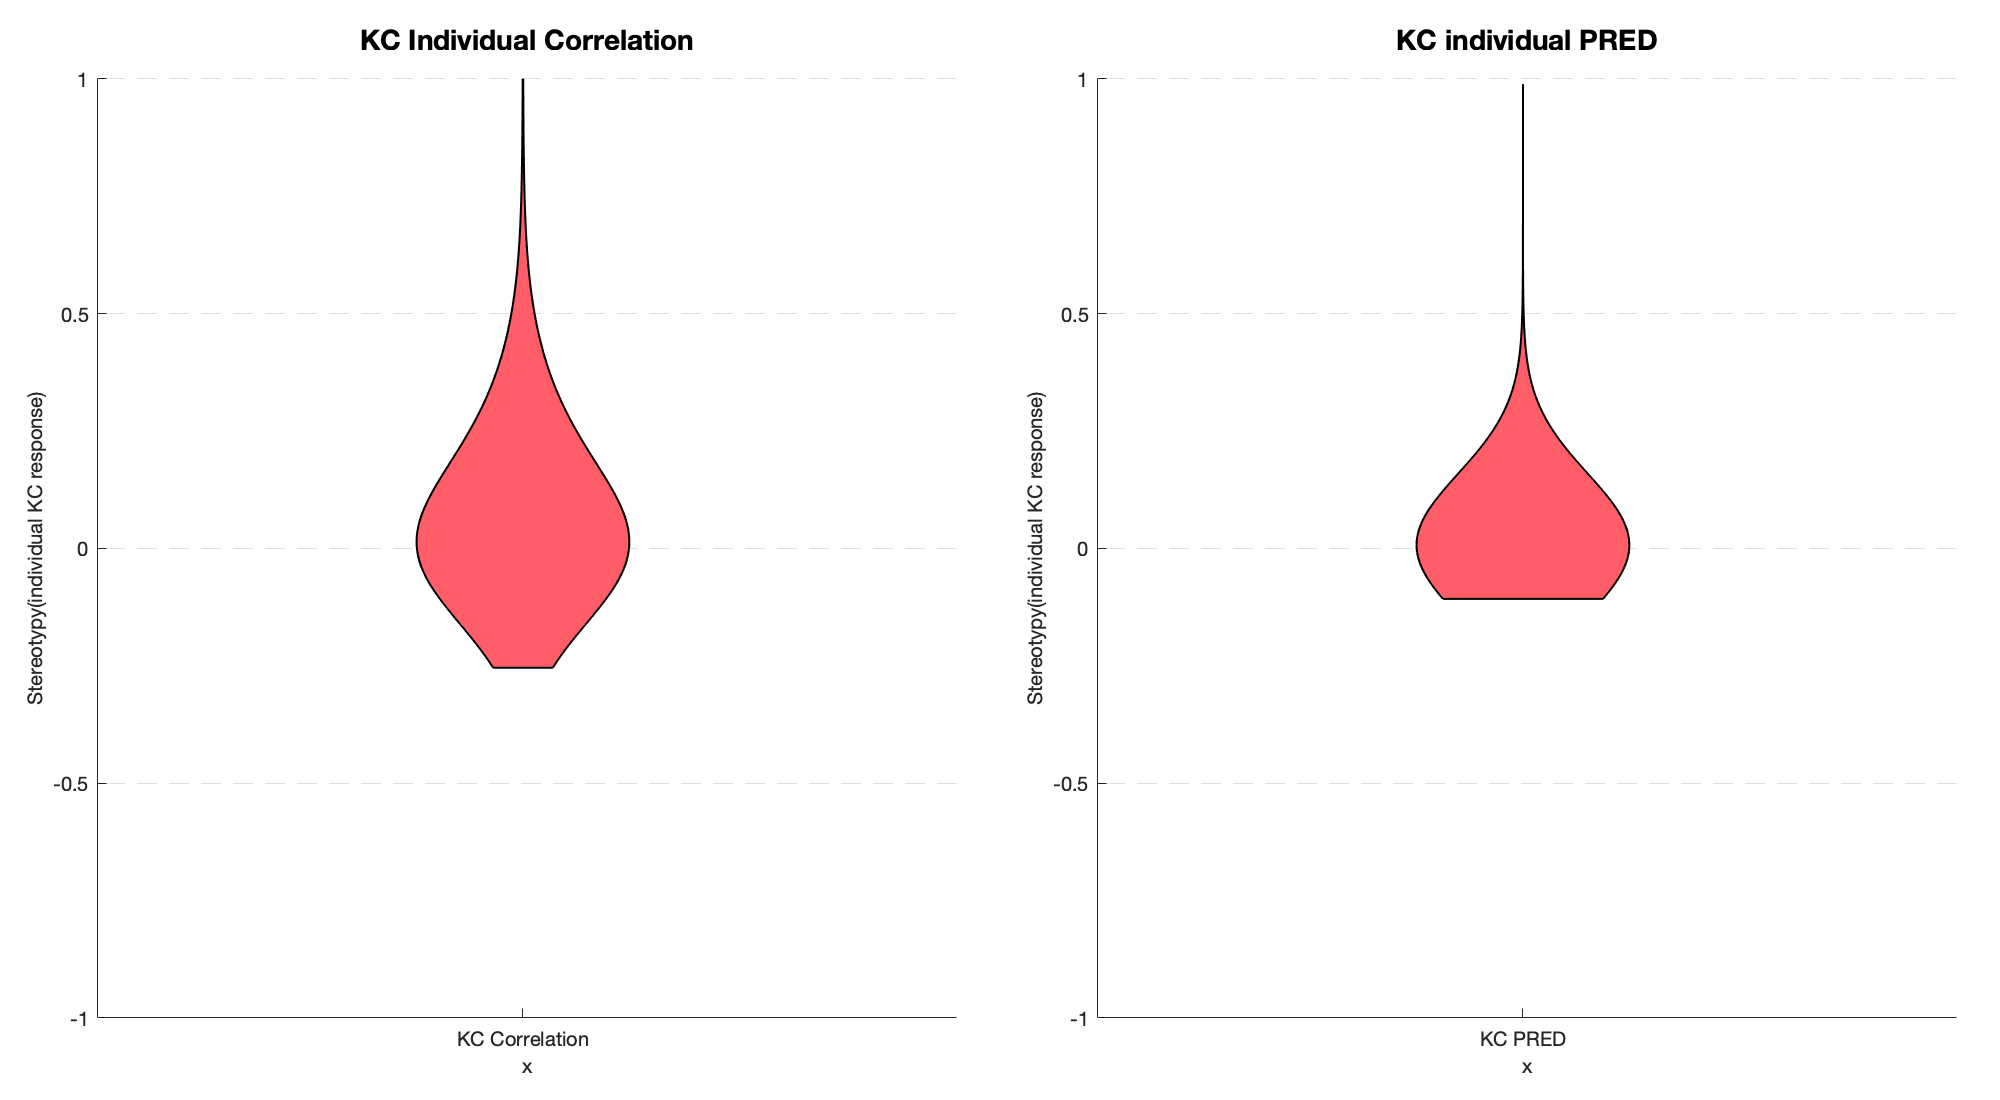

%kc individual correlation violin plot
g1(1,1)=gramm('x',kc_corrcell(:,1),'y',KC_cor(:));
g1(1,1).set_title('KC Individual Correlation');
g1(1,1).set_names('y','Stereotypy(individual KC response)');
g1(1, 1).axe_property('YLim', [-1 1], 'YGrid', 'on', 'YTick', -1:0.5:1, 'GridLineStyle', '--');
g1(1, 1).stat_violin('normalization', 'width', 'fill', "face", 'width', 0.3, 'bandwidth', 0.15);

%kc individual PRED violin plot
g1(1,2)=gramm('x',kc_predcell(:,1),'y',KC_indPREDstereotypy(:));
g1(1,2).set_title('KC individual PRED');
g1(1,2).set_names('y','Stereotypy(individual KC response)');
g1(1,2).axe_property('YLim', [-1 1], 'YGrid', 'on', 'YTick', -1:0.5:1, 'GridLineStyle', '--');
g1(1,2).stat_violin('normalization', 'width', 'fill', "face", 'width', 0.3, 'bandwidth', 0.15);


figure('Position',[100 100 1000 550]);

g1.draw();

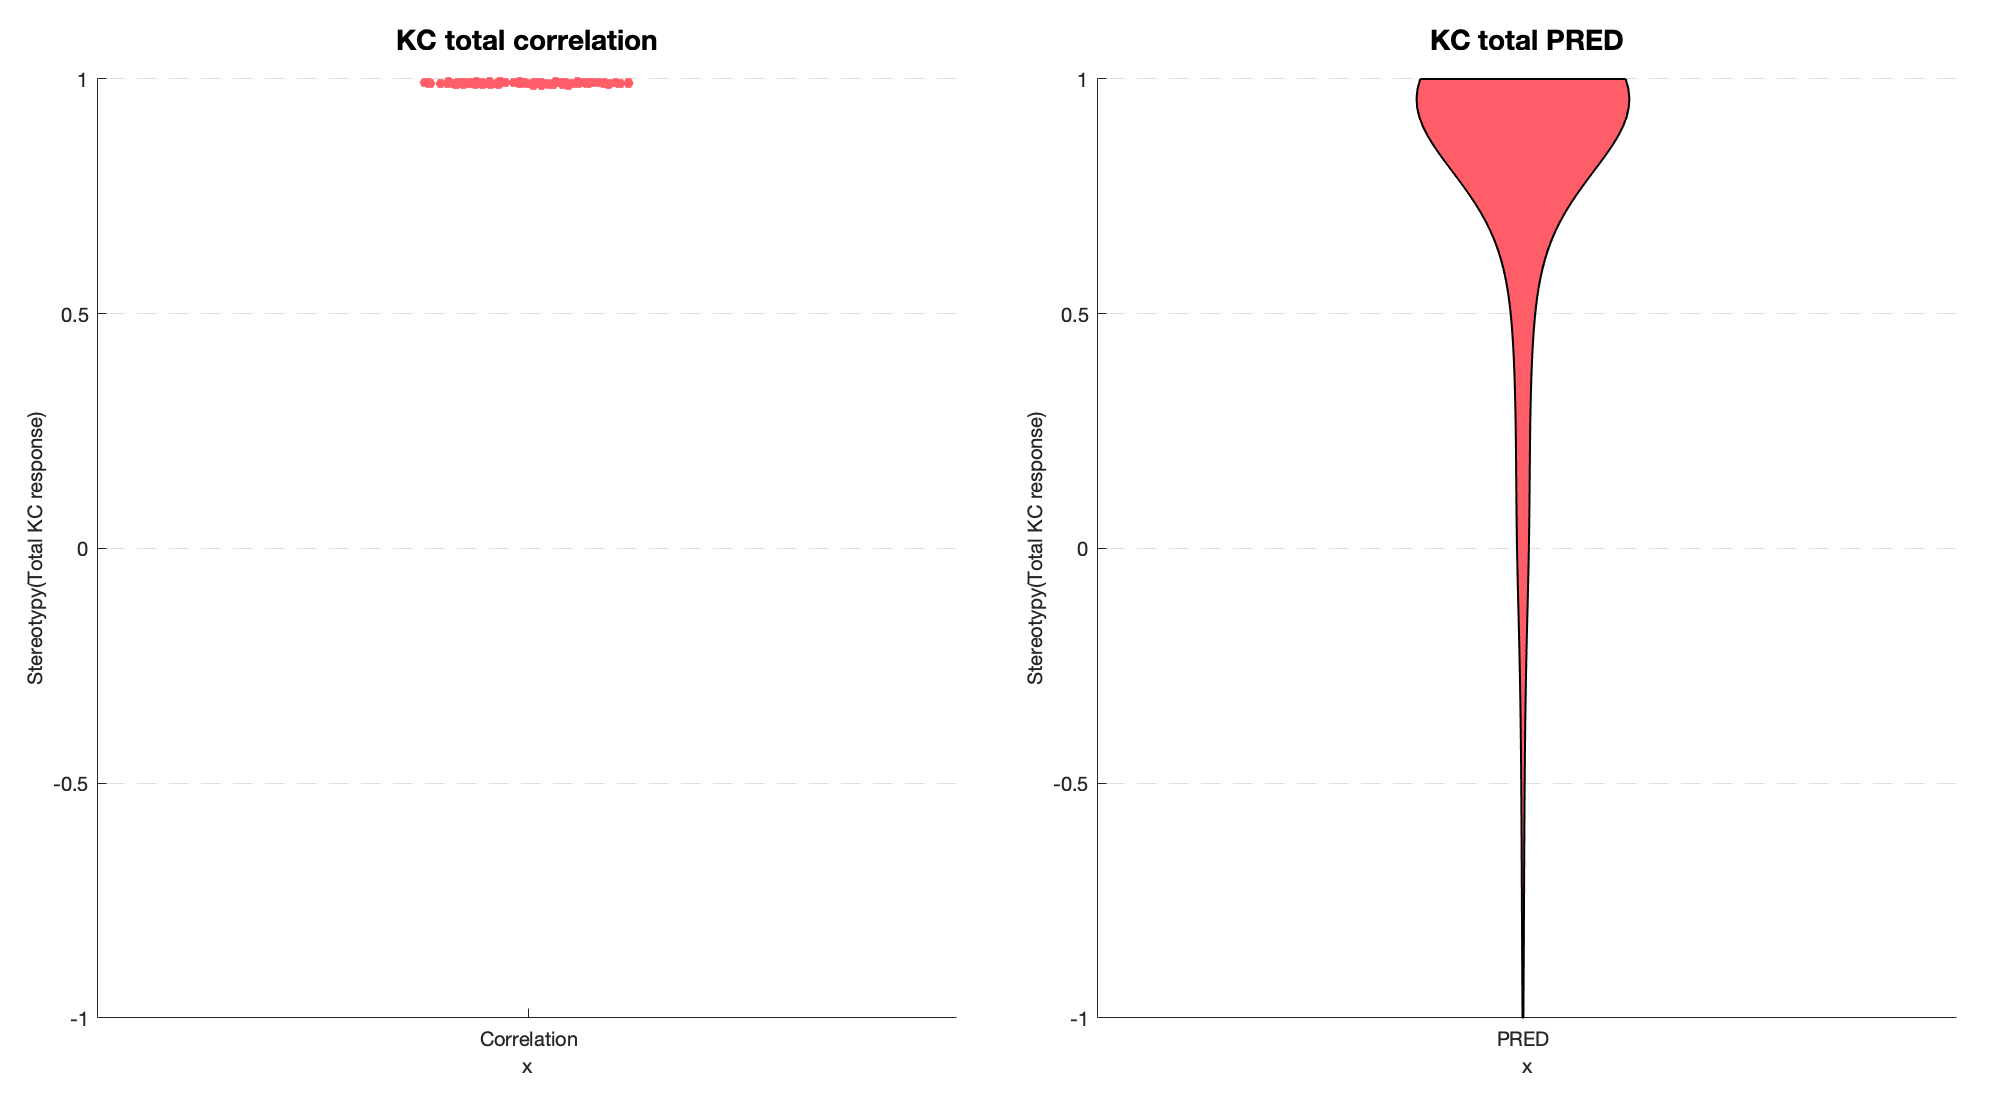

%KC total correlation
g2(1,1)=gramm('x',corrcell(:,1),'y',KC_totcor);
g2(1,1).set_title('KC total correlation');
g2(1,1).set_names('y','Stereotypy(Total KC response)');
g2(1,1).axe_property('YLim', [-1 1], 'YGrid', 'on', 'YTick', -1:0.5:1, 'GridLineStyle', '--');
g2(1,1).geom_jitter('width',0.4,'height',0);

%KC total PRED
g2(1,2)=gramm('x',predcell(:,1),'y',KC_totPREDstereotypy(:));
g2(1,2).set_title('KC total PRED');
g2(1,2).set_names('y','Stereotypy(Total KC response)');
g2(1, 2).axe_property('YLim', [-1 1], 'YGrid', 'on', 'YTick', -1:0.5:1, 'GridLineStyle', '--');
g2(1, 2).stat_violin('normalization', 'width', 'fill', "face", 'width', 0.3, 'bandwidth', 0.15);

figure('Position',[100 100 1000 550]);

g2.draw();

kca=KC_responseA(:,:,1);
kcb=KC_responseB(:,:,1);

%For plotting the correlation between the responses of the KCs in two individuals in a simulation.
kcmatrix=zeros(2000,2000);
for i=1:2000
    for j=1:2000
        kcmatrix(i,j)=corr(kca(i,:)',kcb(j,:)');
    end
end

kcmatrix(isnan(kcmatrix))=0; %to set NaN values to 0

figure
pcolor(kcmatrix(1:50,1:50)) %considering the first 50 KCs for better resolution.
c= colorbar;

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-0.1615 0.7798]
    FontSize: 9
    Position: [0.8496 0.1095 0.0286 0.8155]
       Units: 'normalized'

  Show all properties


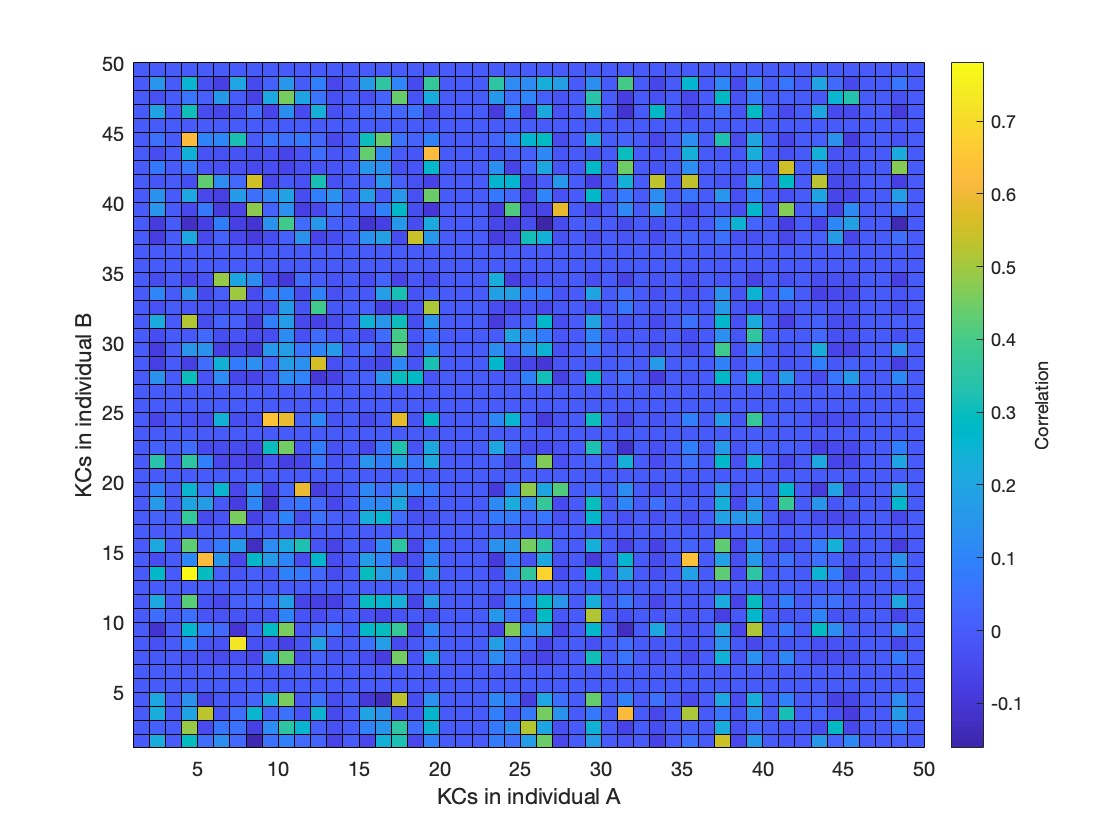

c.Label.String = 'Correlation';
xlabel('KCs in individual A');
ylabel('KCs in individual B');

pna=PN_responseA(:,:,1);
pnb=PN_responseB(:,:,1);

%For plotting the correlation between the responses of the PNs in two individuals in a simulation.
pnmatrix=zeros(50,50);
for i=1:50
    for j=1:50
        pnmatrix(i,j)=corr(pna(i,:)',pnb(j,:)');
    end
end

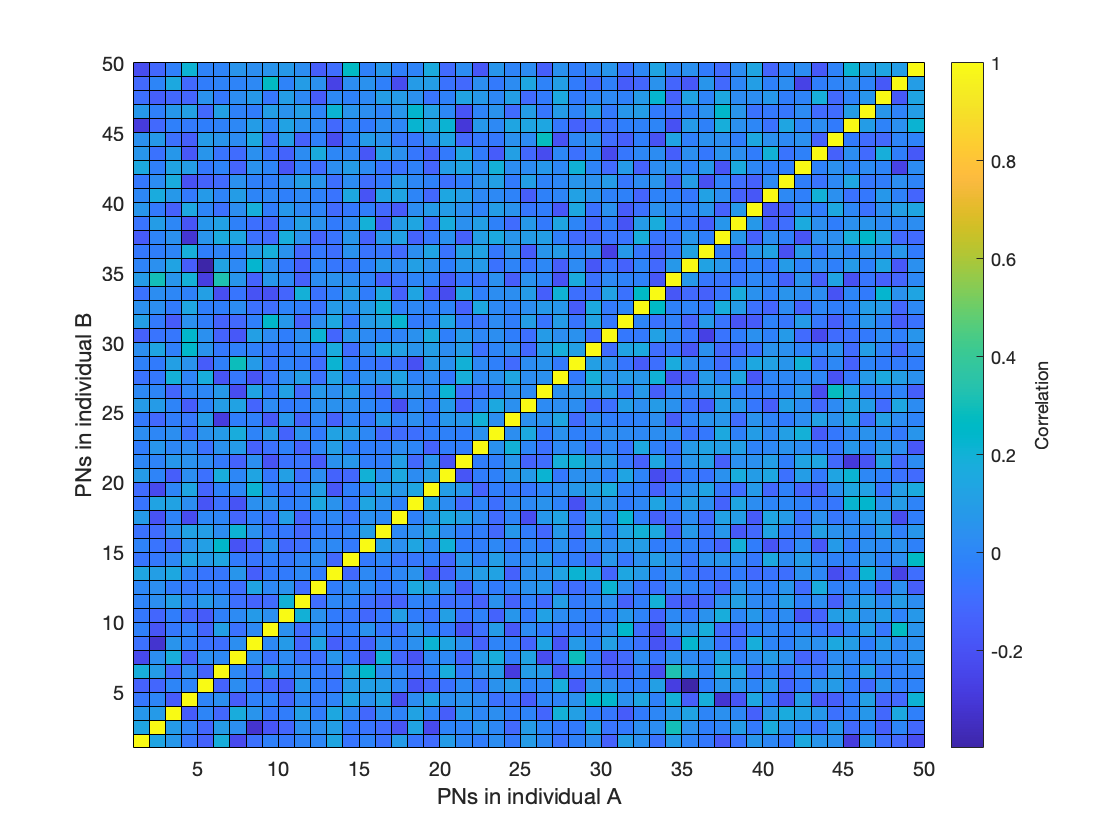

figure
pcolor(pnmatrix);
c=colorbar;
c.Label.String='Correlation';
xlabel('PNs in individual A');
ylabel('PNs in individual B');